# Interactive MATLAB Lab 1.5: Forcing-Function Explorer

In a Live Script, turn A, y0, and v0 into sliders or numeric controls.

A = 0;
y0 = 1;
v0 = 0;

syms x y(x)

forcing = A*exp(3*x);
ode = diff(y,x,2) - 3*diff(y,x) + 2*y == forcing;

Dy = diff(y,x);
conditions = [y(0) == y0, subs(Dy,x,0) == v0];

solution = dsolve(ode,conditions);

verificationResidual = simplify( ...
    diff(solution,x,2) - 3*diff(solution,x) + 2*solution - forcing );

verified = isequal(verificationResidual,sym(0));

if A == 0
    classification = "Homogeneous Linear Equation";
    plotTitle = "Homogeneous Response";
else
    classification = "Nonhomogeneous Linear Equation";
    plotTitle = "Response With External Forcing";
end

disp("Differential equation:")

Differential equation:


disp(ode)

$$\frac{\partial^{2}}{\partial x^{2}}y\left(x\right)-3\,\frac{\partial }{\partial x}y\left(x\right)+2\,y\left(x\right)=0$$

disp("Forcing amplitude A: " + string(A))

Forcing amplitude A: 0


disp("Forcing function:")

Forcing function:


disp(forcing)

$$0$$

disp("Classification: " + classification)

Classification: Homogeneous Linear Equation


disp("Solution:")

Solution:


disp(solution)

$$2\,{\mathrm{e}}^{x}-{\mathrm{e}}^{2\,x}$$

disp("Verification:")

Verification:


disp(verified)

   1



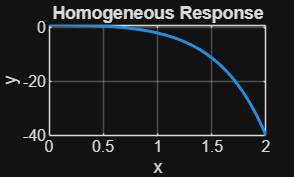


figure
fplot(solution,[0 2],'LineWidth',1.5)
grid on
xlabel('x')
ylabel('y')
title(plotTitle)